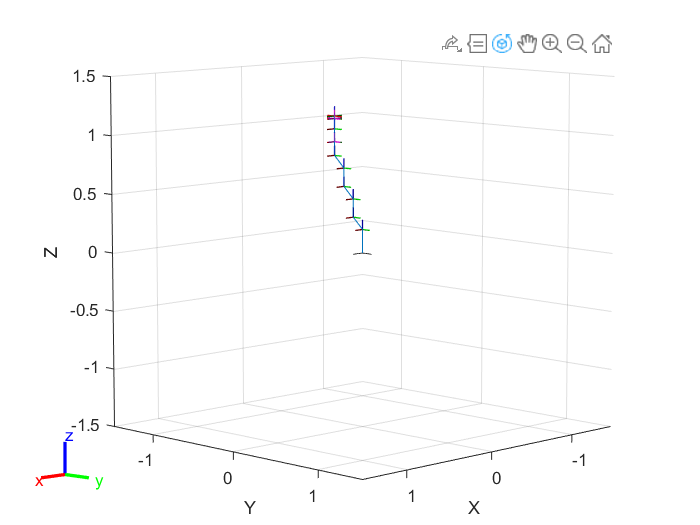

widgetDimensions = [0.02 0.02 0.07];

% Contact parameters
stiffness = 1e4;
damping = 30;
transition_region_width = 1e-4;
static_friction_coef = 1;
kinetic_friction_coef = 1;
critical_velocity = 1;
% импорт робота из файла (стандарт ROS для описания моделей)
robot = importrobot("robot_arm_gripper\urdf\robossembler_arm_gripper.urdf");
% Показываем робота на трёхмерном графике, если Visuals off, тогда меши не
% отображатся
show(robot,"Visuals","off");

% Не помню для чего, можешь сам узнать, но не мешает :)
robot.DataFormat = "column";
% Устанавливаем вектор гравитационных сил
robot.Gravity = [0,0,-9.81];
start_vec = tform2trvec(getTransform(robot,robot.homeConfiguration,"gripper_contact_frame"))

start_vec =     0.3310         0    1.1677


object = [0.3 -0.65 0.225];
place_target = [0.75 0 0.2];

% Вектор перемещений
maxWaypoints = 10;
ee_poses = [start_vec;...
    object+[0,0.1,0];...
    object;... % Начинаем с движения к объекту, при этом открываем гриппер
    object+[0,0,0.05];... % Поднимаем объект вверх
    place_target;... % Двигаемся туда куда ложить, но не бросаем
    place_target+[0,0,-0.1];... % Двигаемся чуть ниже и теперь бросаем
    start_vec]; % Возвращаемся к стартовой позиции
% Вектора ориентаций 
ee_eul = [0,0,0;...
    0,pi/2,pi/2;...
    0,pi/2,pi/2;...
    0,pi/2,pi/2;...
    0,pi,0;...
    0,pi,0;...
    0,0,0];

Tf = cell(1,length(ee_eul));
for i = 1:1:length(ee_eul)
    Tf{i} = trvec2tform(ee_poses(i,:)) * eul2tform(ee_eul(i,:));
end
Tff = cell2mat(Tf)

Tff =     1.0000         0         0    0.3310    0.0000    1.0000    0.0000    0.3000    0.0000    1.0000    0.0000    0.3000    0.0000    1.0000    0.0000    0.3000   -1.0000         0    0.0000    0.7500   -1.0000         0    0.0000    0.7500    1.0000         0         0    0.3310
         0    1.0000         0         0         0    0.0000   -1.0000   -0.5500         0    0.0000   -1.0000   -0.6500         0    0.0000   -1.0000   -0.6500         0    1.0000         0         0         0    1.0000         0         0         0    1.0000         0         0
         0         0    1.0000    1.1677   -1.0000    0.0000    0.0000    0.2250   -1.0000    0.0000    0.0000    0.2250   -1.0000    0.0000    0.0000    0.2750   -0.0000         0   -1.0000    0.2000   -0.0000         0   -1.0000    0.1000         0         0    1.0000    1.1677
         0         0         0    1.0000         0         0         0    1.0000         0         0         0    1.0000         0         0         0 

ts = 0.015;
timeperiod = 2;
TffTimes = 0:timeperiod:length(ee_eul)*timeperiod

TffTimes =      0     2     4     6     8    10    12    14


ik = inverseKinematics("RigidBodyTree",robot);
weights = [1 1 1 1 1 1];
initialguess = robot.homeConfiguration;
[cS1,sI1] = ik('gripper_contact_frame',Tf{2},weights,initialguess);
[cS2,sI2] = ik('gripper_contact_frame',Tf{3},weights,initialguess);
[cS3,sI3] = ik('gripper_contact_frame',Tf{4},weights,initialguess);
[cS4,sI4] = ik('gripper_contact_frame',Tf{5},weights,initialguess);
[cS5,sI5] = ik('gripper_contact_frame',Tf{6},weights,initialguess);
configSeq = [robot.homeConfiguration,...
    cS1,...
    cS2,...
    cS3,...
    cS4,...
    cS5,...
    robot.homeConfiguration];


    
